**ECE537 Programming Assignment 1**

Yuan Sui

1a) Generate N=100 independent sample and plot histogram

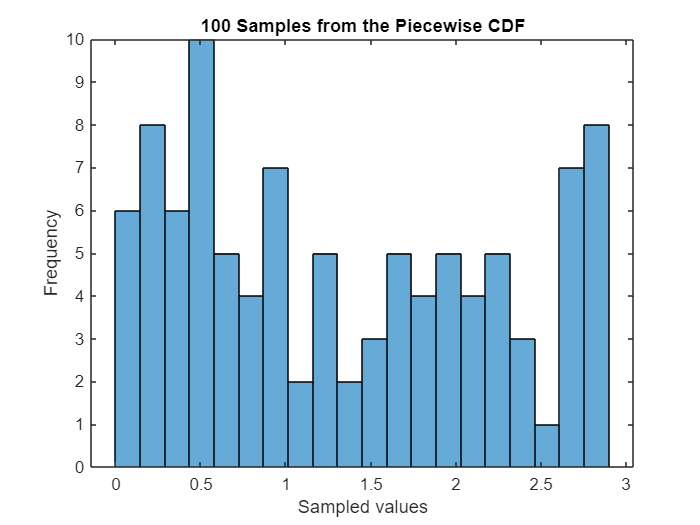

n = 100;

U = rand(n, 1);

samples = F_inv(U);

average = mean(samples);
variance = var(samples);
histogram(samples, 20); % 10 bins for visualization
xlabel('Sampled values');
ylabel('Frequency');
title('100 Samples from the Piecewise CDF');

1b) Expected value is 1.25, emprical average is:

fprintf('Average: %.4f\n', average);

Average: 1.3452


1c) Variance is 0.77, emprical variacance is:

fprintf('Variance: %.4f\n', variance);

Variance: 0.8318


1d) Find N=100, 200, ... samples of Z. Plot average and variance as function of N. They eventually converge to calculated expected value and variance as N increases. 

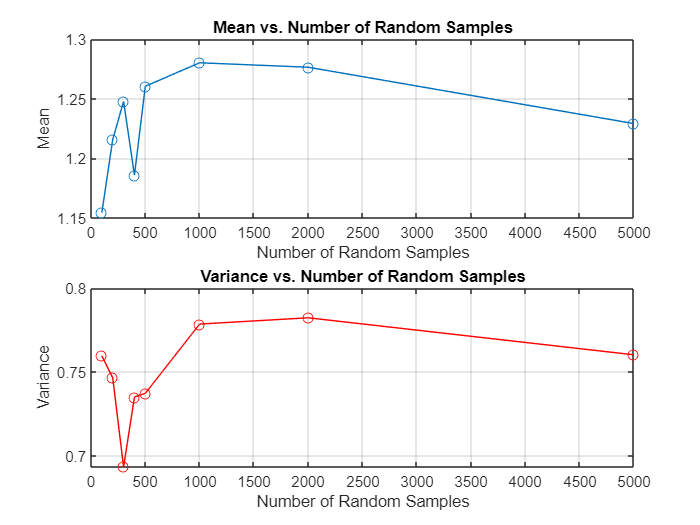

random_counts = [100, 200, 300, 400, 500, 1000, 2000, 5000];

means = zeros(length(random_counts), 1);
variances = zeros(length(random_counts), 1);

for i = 1:length(random_counts)
    
    n = random_counts(i);
    
    U = rand(n, 1);

    samples = F_inv(U);
    
    average = mean(samples);
    variance = var(samples);

    means(i) = mean(samples);
    variances(i) = var(samples);

end

% Plot means and variances
figure; % Create a new figure window
subplot(2, 1, 1); % First subplot for means
plot(random_counts, means, '-o'); % Plot means with markers
xlabel('Number of Random Samples');
ylabel('Mean');
title('Mean vs. Number of Random Samples');
grid on;

subplot(2, 1, 2); % Second subplot for variances
plot(random_counts, variances, '-o', 'Color', 'r'); % Plot variances with markers
xlabel('Number of Random Samples');
ylabel('Variance');
title('Variance vs. Number of Random Samples');
grid on;

2a) Generate N= 100 independent samples of (X,Y)

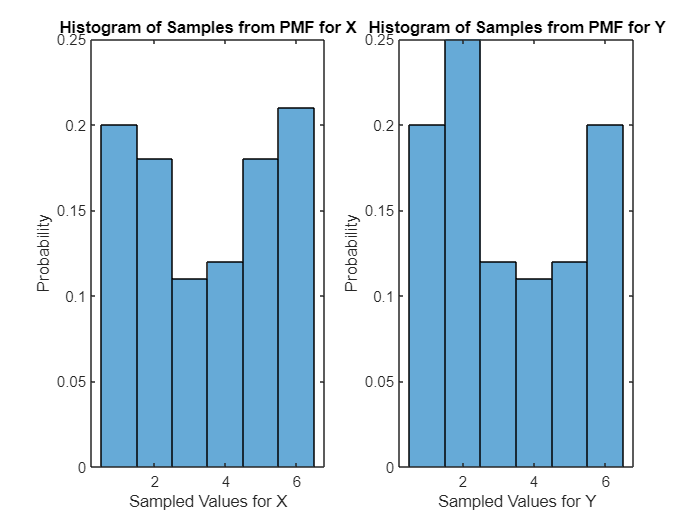

% Define the number of samples
n = 100; % Number of samples to generate

% Generate uniform random samples for X and Y
U_X = rand(n, 1); % Random values for X
U_Y = rand(n, 1); % Random values for Y

% Apply the inverse CDF to generate samples for X and Y
samples_X = F_inv2(U_X);
samples_Y = F_inv2(U_Y);

% Calculate average and variance for X and Y
average_X = mean(samples_X);
variance_X = var(samples_X);
average_Y = mean(samples_Y);
variance_Y = var(samples_Y);

% Plot histograms of the samples for X and Y
figure;

subplot(1, 2, 1);
histogram(samples_X, 'Normalization', 'probability', 'BinEdges', 0.5:1:6.5);
xlabel('Sampled Values for X');
ylabel('Probability');
title('Histogram of Samples from PMF for X');

subplot(1, 2, 2);
histogram(samples_Y, 'Normalization', 'probability', 'BinEdges', 0.5:1:6.5);
xlabel('Sampled Values for Y');
ylabel('Probability');
title('Histogram of Samples from PMF for Y');

% Joint Counts Matrix
joint_counts = zeros(6, 6); % 6x6 matrix for the joint distribution

% Count occurrences of each (X, Y) pair
for i = 1:n
    joint_counts(samples_X(i), samples_Y(i)) = joint_counts(samples_X(i), samples_Y(i)) + 1;
end

% Convert counts to probabilities (joint empirical PMF)
joint_pmf = joint_counts / n;
disp(array2table(joint_pmf, ...
    'VariableNames', {'Y=1', 'Y=2', 'Y=3', 'Y=4', 'Y=5', 'Y=6'}, ...
    'RowNames', {'X=1', 'X=2', 'X=3', 'X=4', 'X=5', 'X=6'}));

           Y=1     Y=2     Y=3     Y=4     Y=5     Y=6 
           ____    ____    ____    ____    ____    ____

    X=1    0.05    0.03       0    0.02    0.04    0.06
    X=2    0.01    0.05    0.04    0.03    0.02    0.03
    X=3    0.02    0.04    0.01       0    0.02    0.02
    X=4    0.03    0.05       0       0    0.01    0.03
    X=5    0.03    0.05    0.03    0.05       0    0.02
    X=6    0.06    0.03    0.04    0.01    0.03    0.04



2b) X and Y are independent variable. By definition, X and Y are independent if P[X=x & Y=y]=P[X=x]*P[Y=y].

From the following heat map, we can tell that in the top left area (1<=X<=2 & 1<=Y<=2) the joing PMF is around 0.25*0.25=0.0625

In the bottom right area (3<=X<=6 & 3<=Y<=6) the joing PMF is around 0.125*0.125=0.0156

Same for top right and bottom left, (3<=X<=6 & 1<=Y<=2) and  (1<=X<=2 & 3<=Y<=6) the joing PMF is around 0.125*0.25=0.05125

Therefore. X and Y are indpendent variable. 

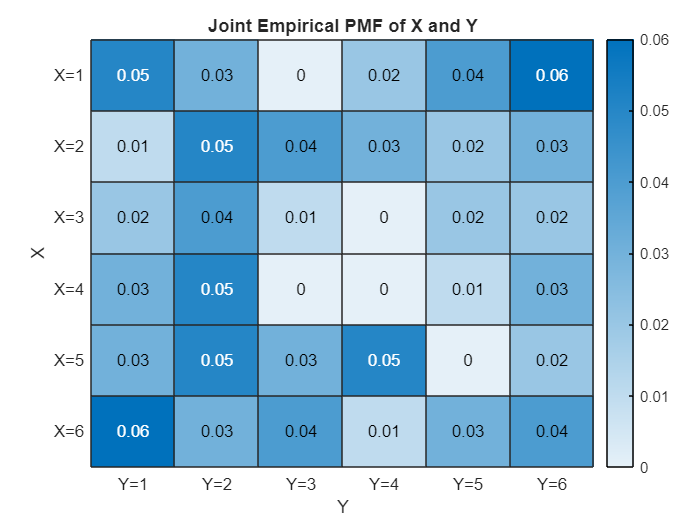

figure;
heatmap({'Y=1', 'Y=2', 'Y=3', 'Y=4', 'Y=5', 'Y=6'}, ...
        {'X=1', 'X=2', 'X=3', 'X=4', 'X=5', 'X=6'}, ...
        joint_pmf);
xlabel('Y');
ylabel('X');
title('Joint Empirical PMF of X and Y');

2c) Define Z1 = X + Y and Z2 = X-Y

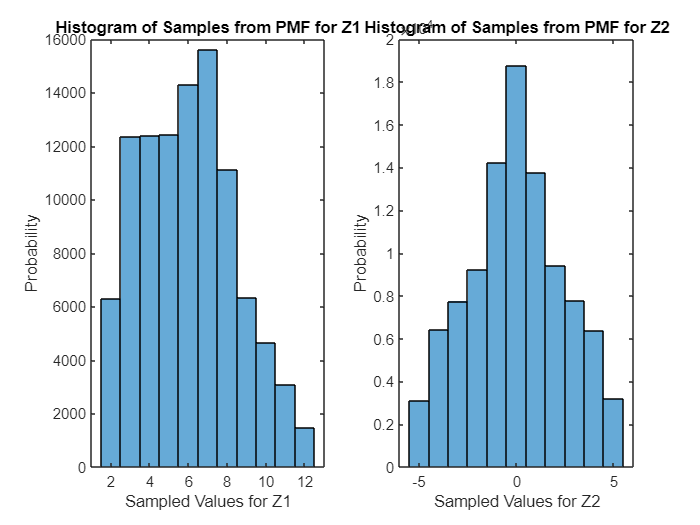

% Define the number of samples
n = 100000; % Number of samples to generate

% Generate uniform random samples for X and Y
U_X = rand(n, 1); % Random values for X
U_Y = rand(n, 1); % Random values for Y

% Apply the inverse CDF to generate samples for X and Y
samples_X = F_inv2(U_X);
samples_Y = F_inv2(U_Y);

Z1 = samples_X + samples_Y;
Z2 = samples_X - samples_Y;

% Plot histograms of the samples for X and Y
figure;

subplot(1, 2, 1);
histogram(Z1);
xlabel('Sampled Values for Z1');
ylabel('Probability');
title('Histogram of Samples from PMF for Z1');

subplot(1, 2, 2);
histogram(Z2);
xlabel('Sampled Values for Z2');
ylabel('Probability');
title('Histogram of Samples from PMF for Z2');

Z1 and Z2 are not independent variables. As shown by the joint PMF, the probability of Z1 changes drastically as Z1 changes.

Which mean that the conditional probability P[Z1=z1 & Z2=z2] = P[Z1=z1]*P[Z2=z2] doesn't stand. 

% Adjust Z2 to avoid negative indices
Z2_shifted = Z2 + 7;  % Shift Z2 so its range starts at 1
Z1_shifted = Z1 - 1; % Shift Z1 so its range starts at 1

% Initialize joint counts matrix
joint_counts = zeros(11, 13); % 11x13 matrix for the joint distribution (Z1: 2-12, Z2: -6 to 6 shifted to 1-13)

% Count occurrences of each (Z1, Z2_shifted) pair
for i = 1:n
    joint_counts(Z1_shifted(i), Z2_shifted(i)) = joint_counts(Z1_shifted(i), Z2_shifted(i)) + 1;
end

% Convert counts to probabilities (joint empirical PMF)
joint_pmf = joint_counts / n;

% Display PMF as a table
disp(array2table(joint_pmf, ...
    'VariableNames', {'Z2=-6', 'Z2=-5', 'Z2=-4', 'Z2=-3', 'Z2=-2', 'Z2=-1', 'Z2=0', 'Z2=1', 'Z2=2', 'Z2=3', 'Z2=4', 'Z2=5', 'Z2=6'}, ...
    'RowNames', {'Z1=2', 'Z1=3', 'Z1=4', 'Z1=5', 'Z1=6', 'Z1=7', 'Z1=8', 'Z1=9', 'Z1=10', 'Z1=11', 'Z1=12'}));

             Z2=-6     Z2=-5      Z2=-4      Z2=-3      Z2=-2      Z2=-1      Z2=0       Z2=1       Z2=2       Z2=3       Z2=4       Z2=5      Z2=6
             _____    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    ____

    Z1=2       0            0          0          0          0          0    0.06293          0          0          0          0          0     0  
    Z1=3       0            0          0          0          0     0.0623      

function z = F_inv(U)
    % Initialize output array
    z = zeros(size(U));
    
    % For 0 <= U < 0.5 (first piece)
    idx1 = (U >= 0) & (U < 0.5);
    z(idx1) = 2 * U(idx1);
    
    % For 0.5 <= U < 1 (second piece)
    idx2 = (U >= 0.5) & (U < 1);
    z(idx2) = 4 * U(idx2) - 1;
end

function z = F_inv2(U)
    % Initialize output array
    z = zeros(size(U));
    
    idx1 = (U >= 0) & (U < 0.25);
    z(idx1) = 1; % Corresponds to the first piece

    idx2 = (U >= 0.25) & (U < 0.5);
    z(idx2) = 2; % Corresponds to the second piece

    idx3 = (U >= 0.5) & (U < 0.625);
    z(idx3) = 3; % Corresponds to the third piece

    idx4 = (U >= 0.625) & (U < 0.75);
    z(idx4) = 4; % Corresponds to the fourth piece

    idx5 = (U >= 0.75) & (U < 0.875);
    z(idx5) = 5; % Corresponds to the fifth piece

    idx6 = (U >= 0.875) & (U < 1);
    z(idx6) = 6; % Corresponds to the sixth piece
end